# **KINOVA Gen3 Manipulator Path Planning using STOMP**

This example shows how to plan a collision-free robot path from an initial to a desired end-effector pose using STOMP ([Stochastic trajectory optimization for motion planning](https://ieeexplore.ieee.org/document/5980280))[1].

## Robot Description and Poses

Load the KINOVA Gen3 rigid body tree (RBT) model.

clear; clc; close all; 
robot_name = 'kinovaGen3';
robot = loadrobot(robot_name, 'DataFormat', 'column'); % Note there are different data formats for loading the robot (chosen in the 2nd argument)

Get the number of joints.

numJoints = numel(homeConfiguration(robot));

Specify the robot frame where the end-effector is attached.

endEffector = "EndEffector_Link"; 

Specify initial and desired end-effector poses. Use inverse kinematics (maps from pose to joint angles) to solve for the initial robot configuration given a desired pose.

% Initial end-effector pose
taskInit = trvec2tform([[0.4 0 0.2]])*axang2tform([0 1 0 pi]);

% Compute current robot joint configuration using inverse kinematics
ik = inverseKinematics('RigidBodyTree', robot);
ik.SolverParameters.AllowRandomRestart = false;
weights = [1 1 1 1 1 1];

currentRobotJConfig = ik(endEffector, taskInit, weights, robot.homeConfiguration);

% The IK solver respects joint limits, but for those joints with infinite
% range, they must be wrapped to a finite range on the interval [-pi, pi].
% Since the the other joints are already bounded within this range, it is
% sufficient to simply call wrapToPi on the entire robot configuration
% rather than only on the joints with infinite range.
currentRobotJConfig = wrapToPi(currentRobotJConfig);

% Final (desired) end-effector pose
taskFinal = trvec2tform([0.35 0.55 0.35])*axang2tform([0 1 0 pi]);  
anglesFinal = rotm2eul(taskFinal(1:3,1:3),'XYZ');
poseFinal = [taskFinal(1:3,4);anglesFinal']; % 6x1 vector for final pose: [x, y, z, phi, theta, psi]

% Final configuration
finalRobotJConfig = ik(endEffector, taskFinal, weights, currentRobotJConfig);
finalRobotJConfig = wrapToPi(finalRobotJConfig);

## Collision Meshes and Obstacles

MATLAB has its own collision world functions to check for and avoid collisions (e.g., collisionSphere, collisionBox, etc). Here, we follow the STOMP paper to set up the voxel world and using the signed Euclidean distance function for this purpose, which is a common practice in robotics perception, mapping, and collision avoidance. We shall still use the MATLAB built-in collision object functions to visualize the object for the convenience. See more details in the following helper functions.

helperCreateObstaclesKINOVA;

Visualize the robot at the initial configuration. You should see the obstacles in the environment as well.

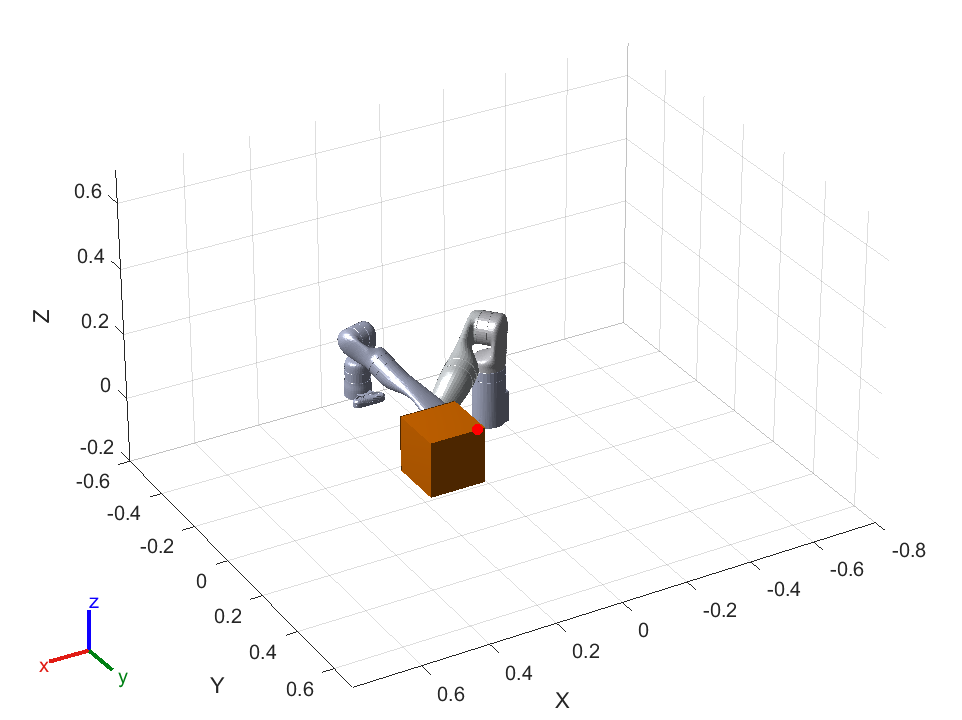

x0 = [currentRobotJConfig', zeros(1,numJoints)];
helperInitialVisualizerKINOVA;

Specify a safety distance away from the obstacles. This value is used in the inequality constraint function of the nonlinear MPC controller.

safetyDistance = 0.05; 

## Path Planning using STOMP

The following helper function contain the setup and execution of the STOMP algorithm for collision-avoidance planning.

历时 1.225803 秒。


Qtheta = 105.4151

RAR = 52.6978

历时 1.311506 秒。


Qtheta = 113.1731

RAR = 52.9954

历时 1.183352 秒。


Qtheta = 110.8393

RAR = 53.0754

历时 1.308993 秒。


Qtheta = 116.6294

RAR = 53.2516

历时 1.314769 秒。


Qtheta = 115.2502

RAR = 53.5537

历时 1.177665 秒。


Qtheta = 117.3795

RAR = 53.7984

历时 1.181232 秒。


Qtheta = 124.5121

RAR = 54.0134

历时 1.164823 秒。


Qtheta = 116.7722

RAR = 54.1201

历时 1.157912 秒。


Qtheta = 113.3357

RAR = 54.2325

历时 1.208605 秒。


Qtheta = 115.6572

RAR = 54.2857

历时 1.172926 秒。


Qtheta = 119.2811

RAR = 54.4513

历时 1.150870 秒。


Qtheta = 117.9400

RAR = 54.7028

历时 1.183702 秒。


Qtheta = 112.1103

RAR = 54.8462

历时 1.126908 秒。


Qtheta = 114.1479

RAR = 55.0606

历时 1.168177 秒。


Qtheta = 108.0823

RAR = 55.1248

历时 1.180575 秒。


Qtheta = 113.0741

RAR = 55.3057

历时 1.162284 秒。


Qtheta = 110.2491

RAR = 55.7135

历时 1.174953 秒。


Qtheta = 106.7874

RAR = 55.8098

历时 1.152616 秒。


Qtheta = 109.0708

RAR = 55.8627

历时 1.146682 秒。


Qtheta = 105.8302

RAR = 55.8186

历时 1.172031 秒。


Qtheta = 104.3300

RAR = 55.8932

历时 1.183861 秒。


Qtheta = 100.7891

RAR = 55.9924

历时 1.150570 秒。


Qtheta = 103.5656

RAR = 56.0656

历时 1.151869 秒。


Qtheta = 102.7904

RAR = 56.2208

历时 1.181135 秒。


Qtheta = 101.0715

RAR = 56.2606

历时 1.174430 秒。


Qtheta = 98.6316

RAR = 56.3380

历时 1.180409 秒。


Qtheta = 98.4991

RAR = 56.4275

历时 1.179376 秒。


Qtheta = 101.4171

RAR = 56.5224

历时 1.211264 秒。


Qtheta = 101.6030

RAR = 56.6283

历时 1.406914 秒。


Qtheta = 101.1845

RAR = 56.8348

历时 1.166547 秒。


Qtheta = 99.8926

RAR = 56.9593

历时 1.173642 秒。


Qtheta = 98.9374

RAR = 57.0192

历时 1.160212 秒。


Qtheta = 95.1648

RAR = 57.0915

历时 1.187960 秒。


Qtheta = 102.1621

RAR = 57.0762

历时 1.185785 秒。


Qtheta = 94.5554

RAR = 57.1589

历时 1.171380 秒。


Qtheta = 100.5986

RAR = 57.4995

历时 1.168105 秒。


Qtheta = 99.5656

RAR = 57.5738

历时 1.204634 秒。


Qtheta = 95.1275

RAR = 57.6437

历时 1.208614 秒。


Qtheta = 96.9829

RAR = 57.6156

历时 1.194514 秒。


Qtheta = 97.5010

RAR = 57.6869

历时 1.151455 秒。


Qtheta = 97.1442

RAR = 57.7362

历时 1.145656 秒。


Qtheta = 95.4861

RAR = 57.8363

历时 1.200397 秒。


Qtheta = 97.2583

RAR = 57.8045

历时 1.175629 秒。


Qtheta = 95.7122

RAR = 57.9316

历时 1.198859 秒。


Qtheta = 96.6489

RAR = 58.0607

历时 1.182723 秒。


Qtheta = 93.6211

RAR = 58.0870

历时 1.160656 秒。


Qtheta = 96.0845

RAR = 58.0446

历时 1.202123 秒。


Qtheta = 97.2241

RAR = 58.1590

历时 1.180076 秒。


Qtheta = 93.4554

RAR = 58.1683

历时 1.184425 秒。


Qtheta = 91.4395

RAR = 58.2260

历时 1.142153 秒。


Qtheta = 90.1819

RAR = 58.4368

历时 1.192932 秒。


Qtheta = 89.0283

RAR = 58.3890

历时 1.192959 秒。


Qtheta = 89.3434

RAR = 58.2097

历时 1.186289 秒。


Qtheta = 88.3199

RAR = 58.3732

历时 1.373061 秒。


Qtheta = 89.9898

RAR = 58.4897

历时 1.188421 秒。


Qtheta = 90.6140

RAR = 58.7401

历时 1.196462 秒。


Qtheta = 88.5813

RAR = 58.8146

历时 1.184908 秒。


Qtheta = 91.4606

RAR = 59.0041

历时 1.143238 秒。


Qtheta = 88.7989

RAR = 58.9402

历时 1.197739 秒。


Qtheta = 88.8402

RAR = 58.8679

STOMP Finished.


isTrajectoryInCollision = logical
   0


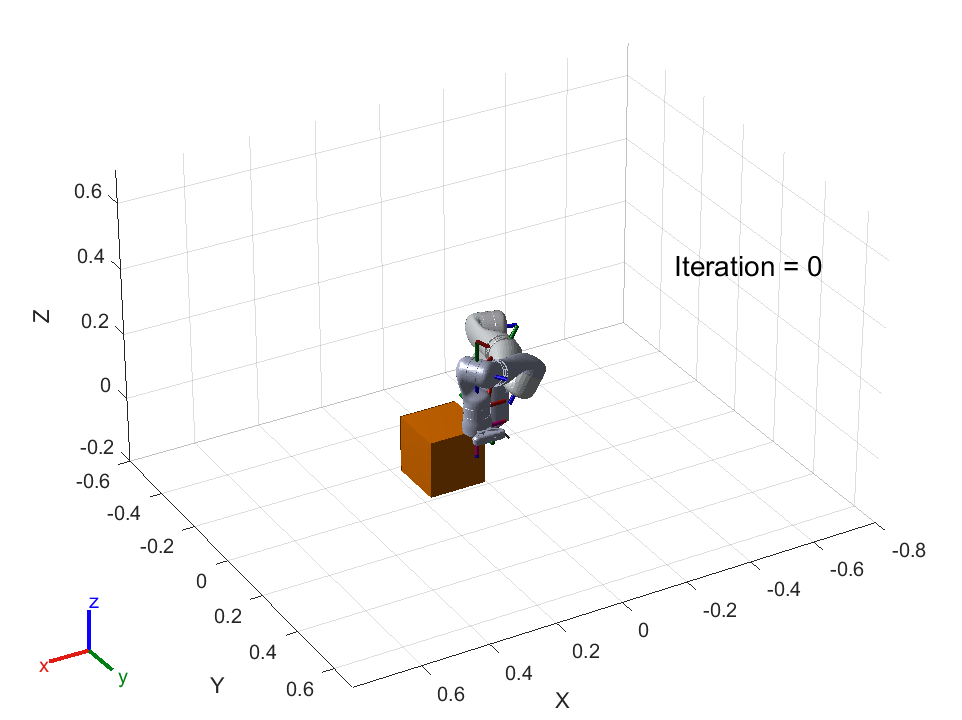

helperSTOMP;

[1] M. Kalakrishnan, S. Chitta, E. Theodorou, P. Pastor and S. Schaal, "STOMP: Stochastic trajectory optimization for motion planning," *2011 IEEE International Conference on Robotics and Automation*, 2011, pp. 4569-4574, doi: 10.1109/ICRA.2011.5980280.